# Estimating and plotting model weights

### Estimating weights

Model weights are estimated using the `infer()` method. This estimation provides a gaussian approximation called the Laplace approximation to the posterior distribution over weights. This gaussian distribution is obtained by an iterative procedure called the Newton method (or Iterative Reweighted Least Square, IRLS) to identify the set of weights $w$ that maximize the log-joint $p(y,w)=p(w)p(y|w)$ where $p(w)$ is the prior over weights and $p(y|w)$ is the likelihood of the weights. You can control this iterative procedure with the following parameters (using the syntax `M.infer('param1',value1, 'param2',value2,...):`

- `'maxiter'` controls the maximum number of iteration (a positive integer; default: `100`)

- `'TolFun'` controls termination tolerance on the log-joint function value, i.e. the convergence criterion (a positive scalar; default: `1e-9`)

- 'initialpoints' controls the number of iterative runs that are run to identify the weights (an integer; default: `10`). This is only for multidimensional models i.e. models with multiplication of regressors. For unidimensional models such as GLM or GAMs, the log-joint is convex and there is a unique maximum

- `'verbose'` controls the output on the command line. Possible values, ranked from less input to more input, are: `'off'`,`'little','on'` (default) and `'full'`

After estimation, the value of weights with their uncertainty and associated statistics are shown by `disp(M)`:

T = load_online_dataset();

loading csv file from url...done


M = gum(T, 'resp ~ Stimulus + lag(response|accuracy; Lags=1:5)','prior','none');
M = M.infer('TolFun',1e-12, 'verbose','full');

Evaluating prior covariance matrix...done
iter 1, log-joint: -30444.448298
iter 2, log-joint: -29399.458605
iter 3, log-joint: -29320.474035
iter 4, log-joint: -29319.760606
iter 5, log-joint: -29319.760535
iter 6, log-joint: -29319.760535
iter 7, log-joint: -29319.760535
iter 8, log-joint: -29319.760535

converged after 8 iterations, log-joint:-29319.760535
Computing posterior covariance...done


disp(M);

Generalized Unrestricted Model (GUM) object: unnamed model
resp ~ Stimulus + lag(response|accuracy; Lags=1:5)
--------------------------------------------------------------------------------
            Type: GLM (   no prior)       Observations:       binomial
   nRegressorSet:          72137     ObservationBlock:              3
   nObservations:          72137          isEstimated:            yes
        isFitted:             no              Dataset:               
     nParameters:             18      nFreeParameters:             18
              df:          72119     nFreeHyperparameters:              0
         scaling:              1        LogLikelihood:  -29319.760535
        LogPrior:              0             LogJoint:  -29319.760535
        accuracy:       0.817015             exitflag:            yes
     LogEvidence:           -Inf            BIC_infer:   58840.874873
       AIC_infer:   586

Note that the Wald statistics are only valid in the frequentist approach, i.e. when declaring `gum(...,'prior','none)`.

During inference, hyperparameters are fixed - use `fit() `instead to jointly fit hyperparameters and estimate weights from data (see [dedicated tutorial](matlab:open('./hyperparameters.mlx'))).

### Plotting weights

Weights are plotted using `M.plot_weights()`. By default, all sets of weights are plotted, each on a dedicated panel. You can choose to plot only the weights for regressor `x1` by calling `M.plot_weights("x1")`;  weights for regressor `x1` and `x2 by `calling `M.plot_weights(["x1","x2"])`;  weights for all regressors *except* `x1` `by `calling `M.plot_weights("-x1").`

In all plots, curves/bars represent the mean of the posterior over weights while the error bars represent the standard deviation.

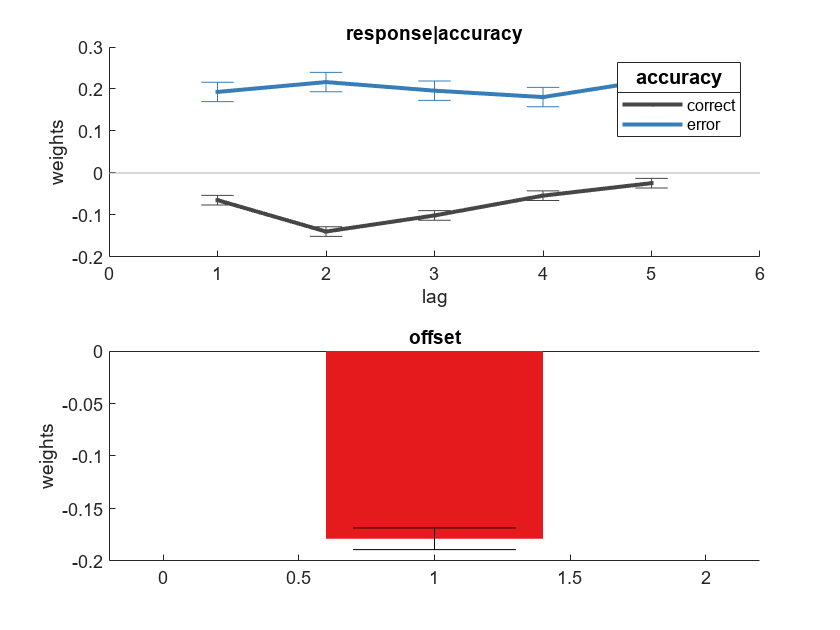

figure;
M.plot_weights("-Stimulus");

The type of plots (e.g. bar or curve) and other plotting options are determined automatically for better visibility, but you can overwrite the default behavior by adding options. In the example below we change the plotting of the weights for previous response to a bar plot (instead of curves) and change the default colour to green and red.

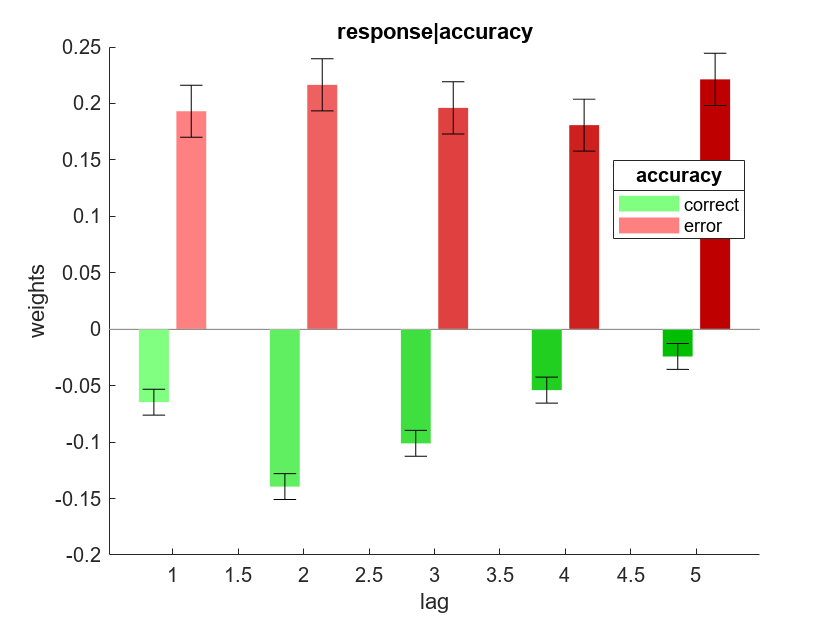

figure;
M.plot_weights("response|accuracy",'bar','color',{'g','r'});

There are many different options for plotting - type  "`help wu"` to learn about them! You can also pass a custom plotting function `fun `for a given set of regressor `x `by calling `M.define_plot("x",fun)`. The function `fun` should return the graphic handles. Here we change the plot of the stimulus weights to a stem plot (the function `stimulus_plot` is defined at the end of this live script).

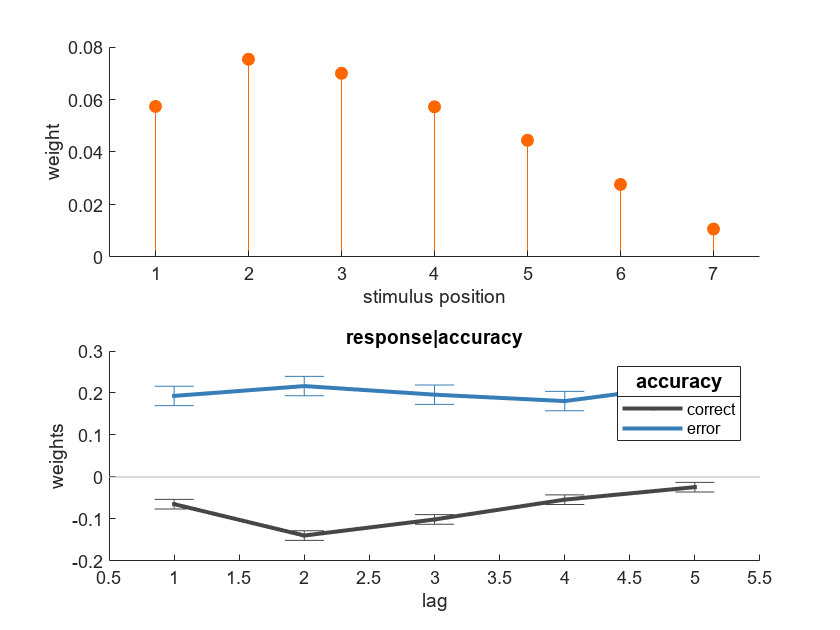

figure;
M = M.define_plot("Stimulus",@stimulus_plot);
M.plot_weights("-offset");

The weight structure for weights can be accessed using `M.get_weight_structure("Stimulus").`

### Bootstrapping

By default the uncertainty about weight estimates are provided by the Laplace approximation in the form of a multivariate gaussian posterior. Weight uncertainty can also be assessed using bootstrapping, which is called using `M.boostrapping()`. The boostraps for each set of weights can then be accessed using `get_weight_structure.`

% Run boostrapping analysis with 200 bootstraps
[M, bootsam] = M.bootstrapping(200);

Computing 200 boostraps for 1 model(s): ********************************************************************************************************************************************************************************************************
 done!



disp("size of bootsample matrix: "+join(string(size(bootsam)),"x"));

size of bootsample matrix: 72137x200



% bootstrap values are in field 'U_bootstrap', 
% confidence intervals in field 'ci_bootstrap'
W = M.get_weight_structure("Stimulus")

W = struct with fields:
             type: 'linear'
            label: "Stimulus"
       dimensions: "Stimulus"
          nWeight: 7
    PosteriorMean: [0.0574 0.0753 0.0700 0.0572 0.0445 0.0277 0.0107]
     PosteriorStd: [0.0030 0.0030 0.0031 0.0031 0.0030 0.0030 0.0030]
                V: []
     PosteriorCov: [7×7 double]
                T: [19.2300 24.8625 22.6567 18.1721 14.6513 9.3354 3.6134]
                p: [2.0764e-82 1.8948e-136 1.1972e-113 8.5860e-74 1.3225e-48 1.0059e-20 3.0216e-04]
            scale: [1 2 3 4 5 6 7]
       constraint: "free"
             plot: @stimulus_plot
            basis: []
         invHinvK: []
    U_allstarting: []
      U_bootstrap: [200×7 double]
      ci_boostrap: [2×7 double]


You can plot the weights using the confidence intervals provided by bootstraps instead of the standard deviation of the weight posterior by using the `'bootstrap'` option in `plot_weights`. By default, these are 95% confidence intervals based on bootstrap quantiles (t`ype "help gum.bootstrapping"` for alternative options).

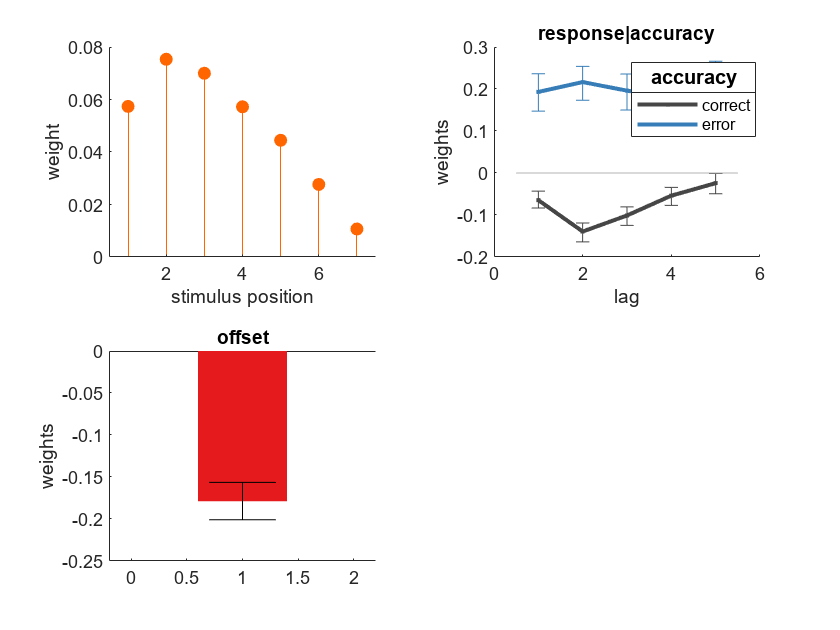

figure;
M.plot_weights([],"bootstrap");

**Next tutorial: **In the [next tutorial](matlab:open('./tutorial6_hyperparameters.mlx')) we explain what are model hyperparameters, how to set them, how to fit them and how to plot them.

function h = stimulus_plot(W)
% example plotting function to be passed in define_plot method.
% The function takes the weight structure as input (here, weights for
% stimulus), plots the weights (here as stem plot) and output plot handles
    h = stem(W.PosteriorMean,'filled','color',[1 .4 0]);
    xlim([.5 W.nWeight+.5]);
    ylabel('weight');
    xlabel('stimulus position');
    box off;
end